**Asimina code**

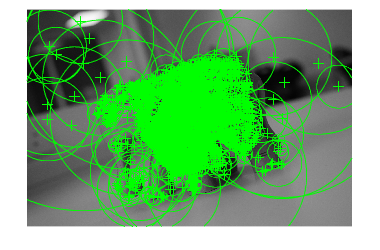

% Automatic keypoint correspondences
I1 = rgb2gray(imread('DSC_0696.jpg'));
I2 = rgb2gray(imread('DSC_0701.jpg'));

% Find feature points using the SIFT algorithm
points1 = detectSIFTFeatures(I1);
points2 = detectSIFTFeatures(I2);

% Extract feature vectors (descriptors)
[features1,validPoints1] = extractFeatures(I1, points1);
[features2,validPoints2] = extractFeatures(I2, points2);

% Plot the selected keypoints
figure; imshow(I1); hold on
plot(validPoints1);

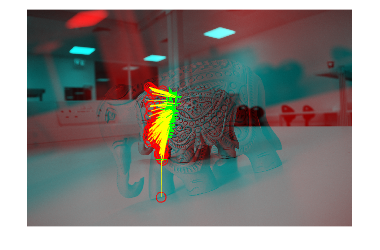


% Match features
indexPairs = matchFeatures(features1, features2);

% Detect keypoint correspondences
matchedPoints1 = validPoints1(indexPairs(100:200,1), :);
matchedPoints2 = validPoints2(indexPairs(100:200,2), :);

% Plot matched corresponding points
figure; showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2);


% Homography - maps inliers in I1 to inliers in I2 - x2 = H*x1 - MSAC for
% outlier

[tform, inlierpoints1, inlierpoints2] = estimateGeometricTransform(matchedPoints1, matchedPoints2, 'projective');

% Homography matrix:
H = tform.T;

pointsimg1 = inlierpoints1.Location;
pointsimg2 = inlierpoints2.Location;

zAxis = ones(length(pointsimg2(:,1)),1);
pn2 = [pointsimg2 zAxis];
pn1 = [pointsimg1 zAxis];

pn1Tr = pn1.';
H2 = H.';

% Project I1 to I2 - x2_1 = H*x1
projectI1toI2 = zeros(length(zAxis),3);
for c = 1:length(zAxis)
    projectI1toI2(c,1) = H2(1,:)*pn1Tr(:,c);
    projectI1toI2(c,2) = H2(2,:)*pn1Tr(:,c);
    projectI1toI2(c,3) = H2(3,:)*pn1Tr(:,c);
end

MSE = immse(double(pn2), projectI1toI2); % Error from projection of 2 to 1
total_number_of_pixels = 65.535*65.535; % JPG image pixels
MSE_normalised = MSE ./ total_number_of_pixels;
fprintf('MSE: %.10f\n', MSE)

MSE: 2278.0112419973


fprintf('MSE per pixel: %.10f\n', MSE_normalised)

MSE per pixel: 0.5304070103
